# Regulation of Food and Drug Craving

Koban, Wager, Kober

Image features (like spatial frequency and color content) can be confounds if they mediate the relationship between brain activity and craving. However, high-level image features may also be enmeshed in the brain with emotional responses, as described in [Kragel et al. 2019, Science Advances](https://www.science.org/doi/pdf/10.1126/sciadv.aaw4358) and other work. In either case, it can be useful to extract image features and test whether they are related to a behavior of interest, like drug or food craving. It might be particularly interesting to test whether image features mediate the relationship between a brain measure (e.g., the Neural Craving Signature, NCS) and craving ratings. 

There are many possible sets of visual features, but deep neural networks can provide some interesting and useful ones. This demo using EmoNet, a model trained to classify visual images into 20 emotion categories. The model is a convolutional neural network based on the popular image recognition network AlexNet. The model is described in [Kragel et al. 2019, Science Advances](https://www.science.org/doi/pdf/10.1126/sciadv.aaw4358).  

The EmoNet website is [here](https://sites.google.com/colorado.edu/emonet/), and it includes a tutorial [here](https://sites.google.com/colorado.edu/emonet/tutorial).  

The trained EmoNet model can be downloaded [here](https://drive.google.com/file/d/1fcbpXKibC8W5iMmEEyItJy-YlTwsdr8I/view?usp=sharing), and the tutorial files (and a copy of the model) [here](https://drive.google.com/file/d/1SDfjHVgmRB-eSdg9fOpZeRpH_HLBhPWH/view?usp=sharing).

For the Craving image dataset, see [here](https://www.dropbox.com/sh/408q2gxu20xki80/AADMyOBaczbrbsKrlSKtcIE_a?dl=0).

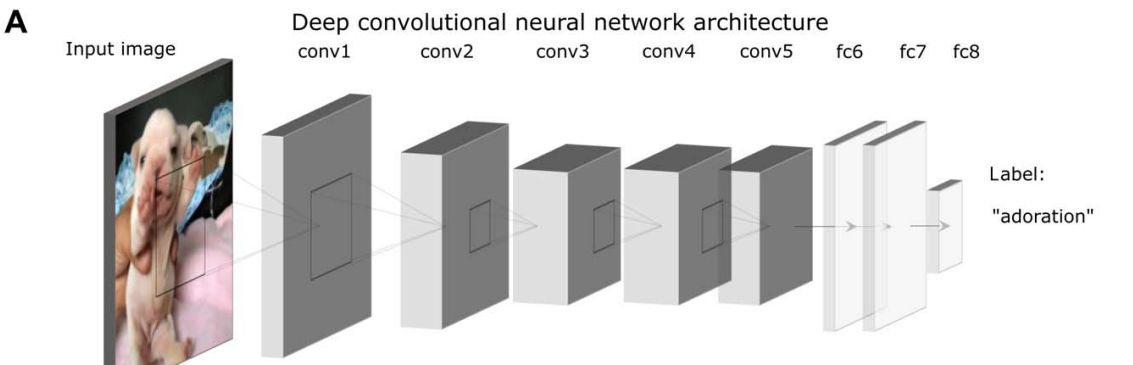

## Logic of testing for confounds

EmoNet output can provide both high-level visual features trained to map onto emotion categories and low-level visual features that represent combinations of edges at particular orientations, shapes, and colors.  Whereas a clear mapping between low-level features and craving could signal a potential confound, a mapping between high-level emotion category features might be thought of as either a confound or a natural relationship between objects and situations depicted in images on the one hand and emotions and behaviors on the other.  If a brain measure's (e.g., NCS) relationship with behavior (e.g., Craving ratings) is completely mediated by visual features, it may be that the brain measure is really picking up on image properties rather than the behavior *per se*. On the other hand, if there is a direct effect of brain on behavior controlling for visual features, a visual confound can be ruled out.  

#### Path diagram for a potential visual confound

NCS -> Image Features -> Craving

For image features to be a confounder, there must be a significant relationship between brain and image features, AND between image features and behavior. If there is convincing evidence that either of these relationships is null (e.g., using Bayes Factors), a visual feature confound can be ruled out as well.

A couple of issues are worth noting.  If image features are strongly predictive of behaviors, as they are with normative ratings of valence and arousal (see [Kragel et al. 2019)](https://www.science.org/doi/pdf/10.1126/sciadv.aaw4358), then it may not be possible to definitively rule out a confound, even if the image features are not on the causal path to the behavior. For example, imagine that people classify images of puppies and spiders into two piles based on which animals they would like to pet. Visual features from EmoNet might classify liking with 100% accuracy, making it very difficult to demonstrate any link between brain and liking independent of these features. However, the visual features do not directly cause liking independent of the brain; the brain is the causal source of the feeling. This means that the inability to demonstrate a direct effect controlling for visual features does not rule out a causal relationship between brain and behavior, it just makes it more difficult to know whether the brain is mainly driven by image features. To test this further, one must find cases where the visual features in question are present but the behavior absent, and vice versa (e.g., using GANs or non-visual induction of behavior). 

Secondly, there are hundreds of thousands of potential visual features. Controlling for all of them is impossible unless there are millions of observations. A sensible strategy if one wants to test a large feature set is to use cross-validation, to train a model that predicts the behavior based on image features in some observations and test the combined model on held-out test observations. Crucially, the error on the test observations must be independent, or the model will find relationships even when none exist (i.e., overfit). Using cross-validation, it is possible to test whether a combination of a large set of low-level visual features (for example) can predict a behavior. 

Finally, ruling out confounds is aided by evaluating whether evidence favors a null effect, as mentioned above. Bayes Factors can provide a basis for inferences that a true relationship with a confound is unlikely.  

## Feature sets in EmoNet

For an input image **I**, The main feature sets of interest are:

**Class probabilities for 20 emotion categories**                 output of netTransfer.predict(I)

**Feature activation values for 20 emotion categories**      netTransfer.activations(I,'fc')

**High-level visual features before mapping to emotions**   netTransfer.activations(I,'fc6')

fc6, fc7 : 4,096 features each

**Low-level features in early convolutional layers**             netTransfer.activations(I,'conv2')

conv1 : 290,400 features

conv2 : 186,624 features

conv3 : 64,896 features

## Load the EmoNet model 

The pre-trained model is stored in the file netTransfer_20cat.mat. This must be on your Matlab path.

%% Get the EmoNet model
model_filepath=which('netTransfer_20cat.mat');
if isempty(model_filepath)
    fprintf('Please download EmoNet from https://sites.google.com/colorado.edu/emonet \n');
end

%% Load EmoNet
load(model_filepath);
% display the network layers
netTransfer.Layers

ans =   23×1 Layer array with layers:

     1   'input'         Image Input                   227×227×3 images with 'zerocenter' normalization
     2   'conv1'         2-D Convolution               96 11×11×3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'         ReLU                          ReLU
     4   'norm1'         Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'         2-D Max Pooling               3×3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'         2-D Convolution               256 5×5×48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'         ReLU                          ReLU
     8   'norm2'         Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'         2-D Max Pooling               3×3 max pooling with s

## Apply the model to ROC Food and Drug Images 

Loop through all ROC images, apply EmoNet, and save layer values, probs, best category

% Process control
doplot = true; % true or false;

% Input files
f = dir('*.jpg');                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        
%f = cellstr(strcat(1, f.name));
%f = strcat(1, f.name);

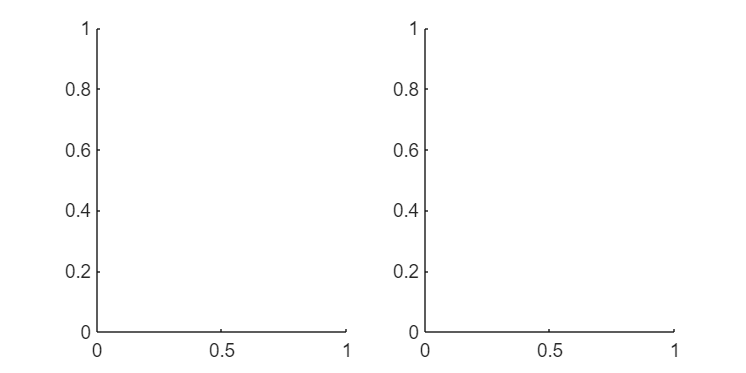



% Outputs
[probs_all, fc8_all] = deal(NaN * zeros(length(f), 20));
Category = cell(length(f), 1);
[CategoryNum, MaxProb] = deal(zeros(length(f), 1));

create_figure('Images', 1, 2);


for i = 1:length(f)
    
    I = imread(f{i});
    
    if doplot || i == 1
        
        create_figure('Images', 1, 2);
        imshow(I)
        axis tight image off
        
    end
    
    I = readAndPreprocessImage(I);
    
    probs = netTransfer.predict(I);
    output_table = table(netTransfer.Layers(23).Classes, probs','VariableNames',{'EmotionCategory','Probability'}); %#ok
    
    probs_all(i, :) = double(probs);
    
    [~, wh] = max(probs);
    Category{i} = output_table.EmotionCategory(wh);
    CategoryNum(i) = wh;
    MaxProb(i) = probs(wh);
    
    fc8_activation = netTransfer.activations(I,'fc');
    fc8_activation = squeeze(double(fc8_activation));
    
    fc8_all(i, :) = fc8_activation';
    
    if doplot || i == 1
        
        subplot(1, 2, 2);
        plot(probs)
        set(gca, 'XTick', 1:20, 'XTickLabel', output_table.EmotionCategory, 'XTickLabelRotation', 90)
        ylabel('EmoNet Probability');
        
        drawnow
        %pause(1)
        
    end
    
end

Brace indexing is not supported for variables of this type.

## Summary table 

% Summarize label probabilities
imgnum = char(f); imgnum = str2num(imgnum(:,1:3));
t = table(f, imgnum, Category, CategoryNum, MaxProb, 'VariableNames', {'Image', 'ImageNum', 'Category', 'CatNumber', 'Prob'});

disp(t)

       Image       ImageNum             Category             CatNumber     Prob  
    ___________    ________    __________________________    _________    _______

    {'002.bmp'}        2       {[Aesthetic Appreciation]}        2        0.73073
    {'005.bmp'}        5       {[Craving               ]}        8              1
    {'007.bmp'}        7       {[Aesthetic Appreciation]}        2        0.87436
    {'008.bmp'}        8       {[Boredom               ]}        6        0.86131
    {'013.bmp'}       13       {[Interest              ]}       15        0.80174
    {'014.bmp'}       14       {[Craving               ]}        8        0.87667
    {'015.bmp'}       15       {[Craving               ]}        8        0.96977
    {'016.bmp'}       16       {[Craving               ]}        8        0.86564
    {'019

## Pie charts of predicted category

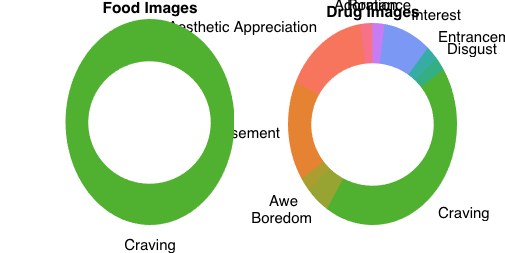

% adapt for each study
if strcmp(pwd, '/Users/leonie.koban/Dropbox/work/BOULDER_PROJECTS/15_Craving/Stimuli/ROC_ALC_fMRI/pics')
    food_nums = 45:88;
    drug_nums = 1:44;
elseif strcmp(pwd, '/Users/leonie.koban/Dropbox/work/BOULDER_PROJECTS/15_Craving/Stimuli/ROC_CIG_FMRI')
    food_nums = 55:108;
    drug_nums = 1:54;
elseif strcmp(pwd, '/Users/leonie.koban/Dropbox/work/BOULDER_PROJECTS/15_Craving/Stimuli/ROC_COC_fMRI')
    food_nums = 1:54;
    drug_nums = 55:108;
end

create_figure('Pie', 1, 2);

% remove empty categories
wh = false(20, 1); wh(t.CatNumber(food_nums)) = true;
labels = cellstr(char(output_table.EmotionCategory))';
labels = labels(wh);

[h, x] = hist([t.Category{food_nums}]);
h = h(wh);  % remove empty categories

colors = seaborn_colors(20);
colors = colors(wh);

% han = pie(h, x);
hh = wani_pie(h, 'colors', colors, 'labels', labels, 'hole', 'hole_size', 15000);
title('Food Images');
axis off

subplot(1, 2, 2)

% remove empty categories
wh = false(20, 1); wh(t.CatNumber(drug_nums)) = true;
labels = cellstr(char(output_table.EmotionCategory))';
labels = labels(wh);

[h, x] = hist([t.Category{drug_nums}]);
h = h(wh);  % remove empty categories

colors = seaborn_colors(20);
colors = colors(wh);

% han = pie(h, x);
hh = wani_pie(h, 'colors', colors, 'labels', labels, 'hole', 'hole_size', 15000);
title('Drug Images');
axis off

## Plot FC8 values across images

% 1-54 = food, 55 and after = drug
colors = seaborn_colors(20);

create_figure('averages fc8', 1, 2)

ans =   Figure (averages fc8) with properties:

      Number: 3
        Name: 'averages fc8'
       Color: [1 1 1]
    Position: [30 1410 2048 1024]
       Units: 'pixels'

  Show all properties



barplot_columns(fc8_all(food_nums, :), 'nofigure', 'nolines', 'noviolin', 'nostars', 'color', colors);

Column   1:	Column   2:	Column   3:	Column   4:	Column   5:	Column   6:	Column   7:	Column   8:	Column   9:	Column  10:	Column  11:	Column  12:	Column  13:	Column  14:	Column  15:	Column  16:	Column  17:	Column  18:	Column  19:	Column  20:	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
       Name        Mean_Value    Std_Error       T           P         Cohens_d
    ___________    __________    _________    _______    __________    ________

    {'Col   1'}      -6.7041      0.41364     -16.208    2.2204e-15     -2.4434
    {'Col   2'}       3.7158      0.41632      8.9253    2.4196e-11      1.3455
    {'Col   3'}       2.9058      0.36266      8.0124    4.5522e-10      1.2079
    {'Col   4'}      -4.304


set(gca, 'XTick', 1:20, 'XTickLabel', output_table.EmotionCategory, 'XTickLabelRotation', 90)
set(gca, 'YLim', [-15 30]);
ylabel('EmoNet fc8 values');
title('Food images')

subplot(1, 2, 2)
barplot_columns(fc8_all(drug_nums, :), 'nofigure', 'nolines', 'noviolin', 'nostars', 'color', colors);

Column   1:	Column   2:	Column   3:	Column   4:	Column   5:	Column   6:	Column   7:	Column   8:	Column   9:	Column  10:	Column  11:	Column  12:	Column  13:	Column  14:	Column  15:	Column  16:	Column  17:	Column  18:	Column  19:	Column  20:	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
       Name        Mean_Value    Std_Error       T           P         Cohens_d
    ___________    __________    _________    _______    __________    ________

    {'Col   1'}     -3.9213       0.73798     -5.3136    3.6033e-06    -0.80106
    {'Col   2'}      4.7551       0.58632        8.11    3.3133e-10      1.2226
    {'Col   3'}      3.6955       0.53777      6.8719    1.9727e-08       1.036
    {'Col   4'}     0.97203

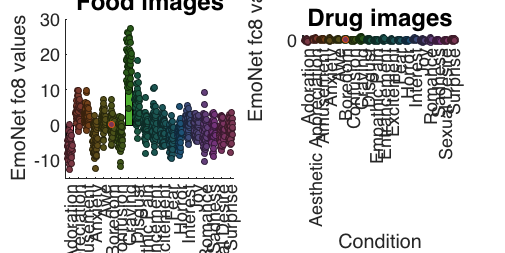


set(gca, 'XTick', 1:20, 'XTickLabel', output_table.EmotionCategory, 'XTickLabelRotation', 90)
set(gca, 'YLim', [-15 30]);
ylabel('EmoNet fc8 values');
title('Drug images')

% Fix axis position problem
subplot(1, 2, 1)
pos = get(gca, 'Position');
pos(2) = 0.2965;
pos(4) = 0.6285;
set(gca, 'Position', pos);

## Plot probability values across images

% 1-54 = food, 55 and after = drug
% CTNA: 1:44 drug, 45:end food

create_figure('average class probabilities', 1, 2)

ans =   Figure (average class probabilities) with properties:

      Number: 4
        Name: 'average class probabilities'
       Color: [1 1 1]
    Position: [30 1410 2048 1024]
       Units: 'pixels'

  Show all properties



barplot_columns(probs_all(food_nums, :), 'nofigure', 'nolines', 'noviolin', 'nostars', 'color', colors);

Column   1:	Column   2:	Column   3:	Column   4:	Column   5:	Column   6:	Column   7:	Column   8:	Column   9:	Column  10:	Column  11:	Column  12:	Column  13:	Column  14:	Column  15:	Column  16:	Column  17:	Column  18:	Column  19:	Column  20:	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
       Name        Mean_Value    Std_Error       T           P         Cohens_d
    ___________    __________    __________    ______    __________    ________

    {'Col   1'}     2.386e-07    2.2753e-07    1.0487       0.30019    0.15809 
    {'Col   2'}     0.0068156     0.0059757    1.1405       0.26037    0.17194 
    {'Col   3'}      0.012746      0.010198    1.2498       0.21812    0.18842 
    {'Col   4'}    2.3872e-


set(gca, 'XTick', 1:20, 'XTickLabel', output_table.EmotionCategory, 'XTickLabelRotation', 90)
set(gca, 'YLim', [0 1]);
ylabel('EmoNet probability values');
title('Food images')

subplot(1, 2, 2)
barplot_columns(probs_all(drug_nums, :), 'nofigure', 'nolines', 'noviolin', 'nostars', 'color', colors);

Column   1:	Column   2:	Column   3:	Column   4:	Column   5:	Column   6:	Column   7:	Column   8:	Column   9:	Column  10:	Column  11:	Column  12:	Column  13:	Column  14:	Column  15:	Column  16:	Column  17:	Column  18:	Column  19:	Column  20:	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
       Name        Mean_Value    Std_Error       T           P         Cohens_d
    ___________    __________    __________    ______    __________    ________

    {'Col   1'}      0.020937       0.01236    1.6939      0.097512    0.25537 
    {'Col   2'}       0.13097      0.038859    3.3703      0.001595     0.5081 
    {'Col   3'}       0.16829      0.048057    3.5018     0.0010909    0.52792 
    {'Col   4'}      0.0193


set(gca, 'XTick', 1:20, 'XTickLabel', output_table.EmotionCategory, 'XTickLabelRotation', 90)
set(gca, 'YLim', [0 1]);
ylabel('EmoNet probability values');
title('Drug images')

% Fix axis position problem
subplot(1, 2, 1)
pos = get(gca, 'Position');
pos(2) = 0.2965;
pos(4) = 0.6285;
set(gca, 'Position', pos);